# CLASE_01_b >> Introducción y fundamentos principales

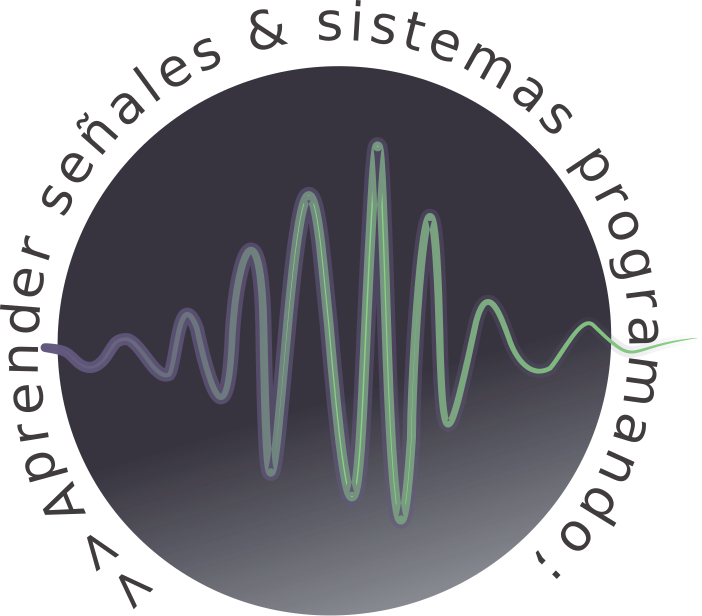

# Temario:

- Entorno de trabajo y ventanas.

- Ayuda y documentación.

- Datos (built-in).

- Variables primitivas.

- Inicialización e indexación de variables matriciales.

- Scripts.

- Introducción a estructuras de control (o sentencias).

- Funciones predefinidas.

- Números complejos.

# Entorno de trabajo y ventanas

MATLAB cuenta con 3 ventanas principales:

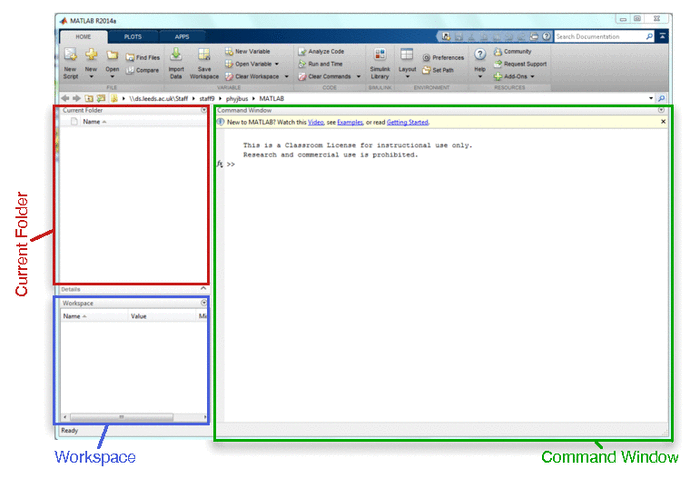

- **Current Folder: **para acceder a nuestro archivos.

- **Command Window: **para ingresar lineas de comandos.

- **Workspace: **explorador de las variables y datos utilizados.

Dentro de la barra de herramientas **Preferences**, permite modificar opciones de todo el entorno de trabajo.

# Ayuda y documentación

La ventaja más importante que tiene MATLAB es su amplia documentacion, soporte y ayuda disponible. Se recomienda dos metodos:

- **Document****acion "Off-line" ---> Help(F1)**

- **Documentación "On-line" ---> **[website mathworks](https://www.mathworks.com/help/)

En el caso de la documentación "off-line":

help sin

 sin    Sine of argument in radians.
    sin(X) is the sine of the elements of X.
 
    See also asin, sind.

    Reference page for sin
    Other functions named sin



Y por otro lado.

doc s   

	S is a variable of type double.



¿Qué pasa si no recuerdo el nombre de la función senoidal o no recuerdo si se escribe sin o sen? 

En MATLAB utilizando la tecla **Tab **es posible completar el codigo

help s

	s is a variable of type double.



Observar que en el caso de **help **el resultado se obtiene *inline *y para **doc **el resultado es en una ventana externa. MATLAB por defecto instala todos los help actualizados al año de la versión del software, para disponer de los mismo sin conexión de internet, lo cual es una gran ventaja.

Por otra parte, MATLAB nos da sugerencias de funciones (la parte de sintaxis de la documentación de la función) en la ventana de comandos haciendo una pausa después de escribir los paréntesis abiertos para los argumentos de entrada de la función.

%mean()

En caso de tener una versión más antigua se puede acceder de manera on-line.

# Datos (built-in)

Se denomina **dato** a cualquier **objeto manipulable por la computadora.** Un dato puede ser un carácter leı́do de un teclado, información almacenada en un disco, un número que se encuentra en la memoria central, etc. Los distintos tipos de datos se representan en diferentes formas: por ejemplo, no se almacena internamente de la misma manera un número entero que un carácter. Aunque los lenguajes de alto nivel permiten en alguna medida ignorar la representación interna de los datos, es preciso conocer algunos conceptos mı́nimos. **A nivel de máquina todos los datos se representan utilizando una secuencia finita de bits**. La definición de un tipo de dato incluye la definición del conjunto de valores permitidos y las operaciones que se pueden llevar a cabo sobre estos valores. Cuando se utiliza un dato en un programa es preciso que esté determinado su tipo para que el **compilador** o **interpretador **sepa cómo debe tratarlo y almacenarlo. Dependiendo del lenguaje puede o no ser preciso declarar expresamente en el programa el tipo de cada dato. No todos los tipos de datos existen en todos los lenguajes de programación. Hay lenguajes más ricos que otros en este sentido [Datos y variables, 2009]. 

## **Trabajando en el command window** 

En las versiones más antiguas:

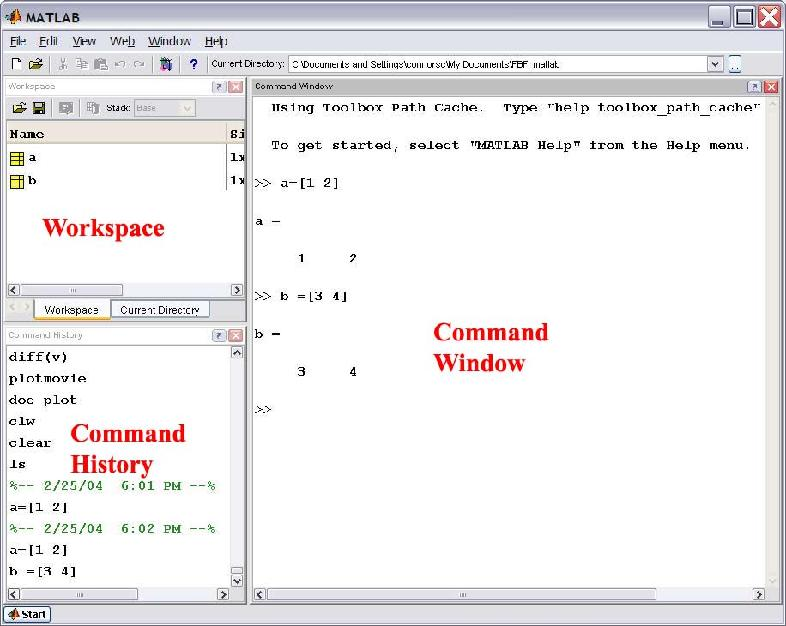

(>>) (**prompt **- mensaje, define un evento o acción) 

Todos los elementos se almacenan en **ans **(answer), que hace referencia a la última respuesta (observar el workspace).

Los tipos de datos básicos, denominados **elementales (o primitivas)** son:

% Números enteros
5, 22, -1

ans = 5

ans = 22

ans = -1

% Números reales (parte entera - parte decimal)
0.009, -31.423, 3.0

ans = 0.0090

ans = -31.4230

ans = 3

% Lógicos (bool)
true, false

ans =    1


ans =    0


% Caracteres (char --> ASCII)
'h', '!', 'A'

ans = h

ans = !

ans = A

Los tipos de datos construidos a partir de datos elementales, se los denomina** estructura de datos**:

% Números complejos (parte real - parte imaginaria)
2+3i, -3i

ans =    2.0000 + 3.0000i


ans =    0.0000 - 3.0000i


% Cadena de caracteres (String)
'Esto es una cadena de caracteres', '123ABC'

ans = Esto es una cadena de caracteres

ans = 123ABC

% Matrices
[1 2 3], [1 2 3;3 4 5; 6 7 8]

ans =      1     2     3


ans =      1     2     3
     3     4     5
     6     7     8


## Operaciones entre datos

%% Operadores aritméticos elementales
% Exponenciación (acento circunflejo)
10^6, 10^-6 

ans = 1000000

ans = 1.0000e-06

% Suma
12 + 123, 5.67 + 0.42

ans = 135

ans = 6.0900

% Resta
123 - 12, 2.13 - 12

ans = 111

ans = -9.8700

% Multiplicación
123 * -12, 34 * 65

ans = -1476

ans = 2210

% División
42 / 2, 123 / -45

ans = 21

ans = -2.7333

Las reglas de prioridad de operaciones son las mismas que en algebra:

- Exponenciaciones.

- Multiplicaciones y divisiones.

- Sumas y restas.

Utilice paréntesis para modificar la prioridad.

%% Operaciones de comparación (entre datos del mismo tipo)
'A' == 'a' % Igual a

ans =    0


1 ~= 0 % No igual (virgulilla)

ans =    1


-12 < 2 % Menor que

ans =    1


31 > 1 % Mayor que

ans =    1


21 <= 2 % Menor o igual que

ans =    0


3 >= 1 % Mayor o igual que

ans =    1



%% Operadores lógicos (entre datos del mismo tipo)
(6 > 10), ~(6 > 10) % Negación

ans =    0


ans =    1


(6 < 10) & (10 > 6) % Conjunción (ampersand)

ans =    1


(0 > 5) | (0 < 5) % Disyunción

ans =    1


# **Variables**

**Los datos pueden ser almacenados en espacios de memoria definidos, para su uso en futuras operaciones, a esto se lo denomina variables:**

Caracteristicas de MATLAB respecto al uso de variables:

- Lenguaje de** tipado dinámico: **quiere decir que **si** **no definimos las variables de manera explícita**, las variables tendrán tipo *double*, que corresponde a números reales con doble precisión (64 bits). En el caso particular de MATLAB, es muy habitual trabajar siempre con valores de tipo *double*, sin cambiar a otros tipos numéricos (*float, int, char)*. Las ganancias en tiempos de ejecución que pueden lograrse al cambiar de un tipo a otro son probablemente marginales, y salvo aplicaciones muy específicas, **es mejor trabajar con los tipos por defecto** sin realizar conversiones de tipos (por el momento).

- Lenguaje **débilmente tipado: dado el valor de una variable de un tipo concreto, no se puede usar como si fuera de otro tipo distinto a menos que se haga una conversión (casting). **Por ejemplo, a la hora de trabajar con valores lógicos. En muchas situaciones donde se requiere un valor de tipo lógico, el lenguaje M admite valores de otros tipos. Por ejemplo, si es un valor numérico, si es igual a 0 asume que es equivalente a un valor lógico falso. Si tiene cualquier otro valor, es verdadero. Si lo que se encuentra es un vector, asume que es falso si el vector está vacío, y verdadero si no lo está [Mat.caminos.upm.es, 2017].

Por otra parte, **no es necesario inicializar las variables,** aunque en algunos casos inicializar y establecer posiciones de memoria previamente puede mejorar el rendimiento de nuestro código (como se verá más adelante).

Comentar <Ctrl+R>

Descomentar <Ctrl+T>

Los shortcuts (atajos) son configurables desde **Preferences.**

## Asignación

Las instrucciones de asignación sirven para almacenar un valor en una variable. En **pseudocodigo** se escribe:


$$\text{a}\leftarrow 2; \\ b\leftarrow-4; \\ c\leftarrow \text{"hola mundo"}; \\d\leftarrow1.31; \\ e\leftarrow true}


$$


En MATLAB, La sintaxis más habitual de una operación de asignación es:

a = 2

a = 2

b = -4

b = -4

c = 'hola mundo'

c = hola mundo

d = 1.31

d = 1.3100

e = true

e =    1


**Observar nuevamente el workspace, ¿Qué cambió?**

Para tener en cuenta con respecto a los nombres de variables:

**Case sensitive (valor explicito)**

a = 5

a = 5

A = 3

A = 3

a1 = 5

a1 = 5

**Primer carácter debe ser una letra**

% 1a = 10

**Utilización de la opción autocompletar (TAB) **(valor implicito)

alturaTriangulo = 3

alturaTriangulo = 3

baseTriangulo = 2

baseTriangulo = 2

% AreaTriangulo = 

# Indexación e inicialización de variables matriciales

## Indexación

Todos los datos en el entorno de MATLAB poseen indice, incluso los datos primitivos.

a = 3,14;

a = 3

a(1)

ans = 3

**MATLAB indexa comenzando en 1**, no en 0 como en otros lenguajes (Python).

La indexación cobra sentido en el uso de matrices. Una matriz en pseudocodigo:


$$\text{A}\leftarrow L_1, L_2,...,L_n \\
B\leftarrow L_{1,1}, L_{1,2},...,L_{i,j}} 


$$


En matrices de una sola fila o una sola columna (vectores):

a = [3 35 19 12]

a =      3    35    19    12


t = a(1)

t = 3

h = a(2:3)

h =     35    19


b = a(2:end)

b =     35    19    12


Para matrices

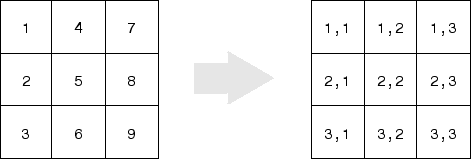

b = [12 3; 31 65]

b =     12     3
    31    65


b(1,1:2)

ans =     12     3


b(:,1)

ans =     12
    31


b(:,1) = [4;5]

b =      4     3
     5    65


## Indexación avanzada

u = [123 3 52 32 2 1]

u =    123     3    52    32     2     1


[minVal, minInd] = min(u)

minVal = 1

minInd = 6

[maxVal, maxInd] = max(u)

maxVal = 123

maxInd = 1

ind = find(u == 9)


ind =

  1×0 empty double row vector



ind = find(u > 2 & u < 50)

ind =      2     4


## Inicialización

Como se mencionó anteriormente MATLAB es de **tipado dinámico**, con lo cual **no es necesario definir de antemano el tipo de variable, ni iniciarla con algún valor en particular**. Ahora bien, inicializar, permite reservar un espacio en memoria de antemano, acortando los tiempos de ejecución (**Prelocalización**). Por ejemplo, si utilizamos algún ciclo de control que modifique o agregue valores a una variable, dicho procedimiento se realizará más rápidamente si el vector esta inicializado con el tamaño que nosotros prevemos.

ones(1,10) % Matriz de unos (Filas, Columnas)

ans =      1     1     1     1     1     1     1     1     1     1


zeros(5,5) % Matriz de ceros

ans =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


eye (2,2) % Matriz identidad

ans =      1     0
     0     1


rand(1,10) % Matriz de números aleatorios

ans =     0.9597    0.3404    0.5853    0.2238    0.7513    0.2551    0.5060    0.6991    0.8909    0.9593


rand(2,3,3) % Hipermatrices

ans = 
(:,:,1) =

    0.5472    0.1493    0.8407
    0.1386    0.2575    0.2543


(:,:,2) =

    0.8143    0.9293    0.1966
    0.2435    0.3500    0.2511


(:,:,3) =

    0.6160    0.3517    0.5853
    0.4733    0.8308    0.5497


nan(2,10) % Acrónimo en inglés Not a Number (no es un número)

ans =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


linspace(0,10,5) % Vector equiespaciado

ans =          0    2.5000    5.0000    7.5000   10.0000


0:2:10

ans =      0     2     4     6     8    10


1:5

ans =      1     2     3     4     5


# Scripts

Hasta el momento trabajamos en el **command window **ingresando lineas de código y ejecutándolos secuencialmente. Esto presenta dos inconvenientes, como mínimo, a la hora de programar varias lineas:

- **No es posible almacenar las lineas de código ingresadas**. Si bien son almacenadas en un command history, no es práctico su uso para nuestro trabajo.

- **Las lineas son ejecutadas a medida que son ingresadas**. Nuevamente esto resulta engorroso, a la hora de testear el código o incluso reemplazar o modificar una linea.

En este sentido debemos recurrir a **archivos de programa**, donde contengan las lineas de código. Existen dos tipos de archivos de programa:

- **Scripts**, que **no aceptan** argumentos de entrada ni devuelven argumentos de salida. Operan sobre datos en el área de trabajo.

- **Funciones**, que **aceptan** argumentos de entrada y devuelven argumentos de salida. Las variables internas son locales para la función.

De todas formas el **command window **cobra relevancia nuevamente cuando comencemos a realizar **debugging** de nuestro codigo, dado que usaremos esta ventana para ingresar comandos de prueba en tiempos de depuración.

edit

En las versiones más antiguas:

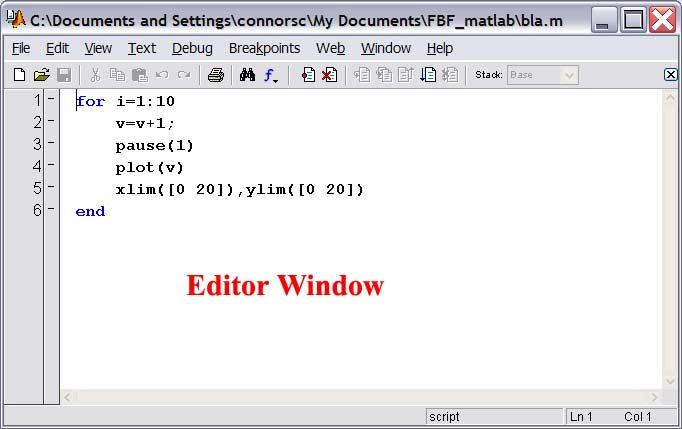

Esta ventana cuenta con varias herramientas para la edición de scripts, para la depuración (debugging) e incluso documentación (hoy obsoleto, reemplazado por liveScript). Vamos a trabajar con ellas, a medida que avancemos con los temas.

Acudimos a la ventana del editor, dado que es más fácil escribir estructuras complejas como las que vamos a trabajar a continuación.

Para programadores nuevos de MATLAB, basta con que cree en la carpeta actual los archivos de programa que desee probar. A medida que  desarrolle más archivos propios, querrá organizarlos en otras carpetas y *toolboxes* personales que pueda agregar a su ruta de búsqueda de MATLAB.

Si duplica nombres de funciones, MATLAB ejecuta aquella que aparece primero en la ruta de búsqueda.

Para ver el contenido de un archivo de programa, por ejemplo, `myfunction.m`, use

type script_01_01.m


clc
clear all

%% Ejercicio 1)
    display('Ejecicio 1')
    a1 = 1i*(1-sqrt(3))*(sqrt(3)+1i)
    b1 = (5i)/(1+1i)
    c1 = (1-1i*sqrt(2))^3

%% Ejercicio 2)
    display('Ejecicio 2')
    a2 = (2 + 1i*sqrt(3))
    b2 = (2 + 1i*sqrt(3))^2

    mod_a2 = abs(a2) 
    mod_b2 = abs(b2)
    ang_a2 = angle(a2)*180/pi 
    ang_b2 = angle(b2)*180/pi
    compass(a2,'r');title('Representacion fasorial de un numero complejo'); hold on; compass(b2,'-g'); hold off;

% Ejercicio 3)
    display('Ejecicio 3')
    numerador = (1+1i);
    denominador = (sqrt(3)+1i);
    a3 = numerador/denominador
    mod1 = abs(numerador);
    mod2 = abs(denominador);
    ang1 = angle(numerador);
    ang2 = angle (denominador);
    b3 = (mod1*exp(1i*ang1))/(mod2*exp(1i*ang2))

% Ejercicio 4)
    display('Ejecicio 4')
    a4 = 1*exp(1i)+ 1*exp(3i)
    mod_a4 = abs(a4)
    ang_a4 = angle(a4)


Trabajemos con scripts, los cuales pueden operar en datos existentes en el área de trabajo, o  pueden crear datos nuevos en los cuales operar. Aunque los scripts no devuelven argumentos de salida, cualquier variable creada por ellos  permanece en el área de trabajo para ser utilizada en cálculos posteriores. Además, los scripts pueden producir gráficas mediante el uso de funciones como plot.

# Introducción a estructuras de control (o sentencias)

Comencemos a realizar los priemros scripts utilizando las estructuras esenciales: **bucles** y **condicionales. ** Los bucle permiten ejecutar varias tareas idénticas secuencialmente con la variación de diversos índices; se pueden encapsular con otros contadores y con otras sentencias. Por otra parte, los condicionales permiten incluir variaciones en la ejecución del código según el cumplimiento de ciertas condiciones lógicas. Estos no son las únicas estructuras de programación, por lo contrario son las más básicas. A partir de ellas se derivan sentencias más útiles y más específicas como veremos a continuación.

La mayoria de las estructuras de control trabajan con operadores, para identificarlos ingresar el siguiente código:

help .

  Operators and special characters.
 
  Arithmetic operators.
    plus       - Plus                               +    
    uplus      - Unary plus                         +    
    minus      - Minus                              -    
    uminus     - Unary minus                        -    
    mtimes     - Matrix multiply                    *    
    times      - Array multiply                    .*    
    mpower     - Matrix power                       ^    
    power      - Array power                       .^    
    <a href="matlab:help mldivide">mldivide</a

## **Sentencia condicional finita**

La estructura más basica y común a todos los lenguajes es ***if / else / elseif***. Estructura de control que responde a condiciones establecido con **operadores logicos** (AND, OR, NOT, entre otros) y **operadores de comparación** (==, ~=, <, >, entre otros).

A continuacion algunos ejemplos en pseudocódigo y su respectiva sintaxis :


$$\textbf{Si} \text{ condición } \textbf{Entonces} \\ \qquad \text{instruciones;}
\\ \textbf{Fin Si}$$


input = 3;
if input > 0 && input < 10
    display(input) 
end 

input = 3


$$\textbf{Si} \text{ condición } \textbf{Entonces} \\ \qquad \text{instruciones1;}
\\ \textbf{Si no } \textbf{Entonces} \\ \qquad \text{instruciones2;}
\\ \textbf{Fin Si}$$


input = -3;
if input > 0 && input < 10
    display(input) 
else
    display('No cumple la condición')
end 

No cumple la condición



$$\textbf{Si} \text{ condición1 } \textbf{Entonces} \\ \qquad \text{instruciones1;}
\\ \textbf{Si no } \text{condición2 } \textbf{Entonces} \\ \qquad \text{instruciones2;}
\\ \textbf{Si no } \text{condición3 } \textbf{Entonces} \\ \qquad \text{instruciones3;}
\\ \text{...} 
\\ \textbf{Entonces} \\ \qquad \text{instrucionesN;}
\\ \textbf{Fin Si}$$


input = 2;  % probar con string y matrices
if isnumeric(input) && length(input) > 1  
    display(sum(input)) 
elseif isnumeric(input) && length(input) == 1
    display(input)  
else
    display('No cumple la condición')
end 

input = 2

La representación en diagrama de flujo:

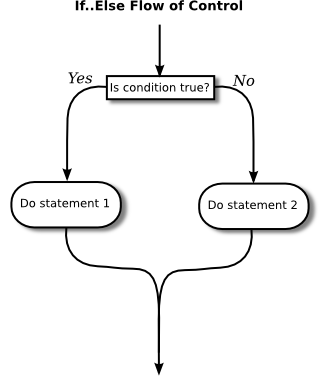

*Es importante que evitemos estructuras lógicas muy complejas, porque son difíciles de entender y de depurar; aún cuando las ha escrito uno mismo. *

## **Sentencia condicional por casos**

La sentencia **switch** realiza una función análoga a un conjunto de if...elseif concatenados. Se usa con frecuencia cuando existe una serie de opciones de ruta para una variable dada, dependiendo de su valor:

A continuacion algunos ejemplos en pseudocódigo y su respectiva sintaxis :


$$\textbf{Según} \text{ variable } \textbf{Hacer} \\ \qquad \textbf{caso} \text{ valor1; }
\\ \qquad \qquad  \text{instruciones1;}
\\ \qquad \textbf{caso} \text{ valor2; }
\\ \qquad \qquad  \text{instruciones2;}
\\ \qquad \textbf{caso} \text{ valor3; }
\\ \qquad \qquad  \text{instruciones3;}
\\ \qquad  \text{...} 
\\ \qquad  \textbf{Si no } \textbf{Entonces} \\ \qquad \qquad   \text{instrucionesN;}
\\ \textbf{Fin Si}$$


[dayNum, dayString] = weekday(date, 'long', 'local');

switch dayString
    case {'Lunes', 'Monday'}
      disp('Comienzo de la semana.')
    case {'Martes', 'Tuesday'}
      disp('Segundo día de la semana.')
   case {'Miercoles', 'Wednesday'}  
      disp('Mitad de semana.')
    case {'Jueves', 'Thursday'}
      disp('Casi se termina.')
   case {'Viernes','Friday'}
      disp('Viernes!!!')
   otherwise
      disp([dayString,' - Fin de semana'])
end

Comienzo de la semana.


## Sentencia condicional infinita

Otro tipo de bucle son los condicionales, **while. **A continuacion algunos ejemplos en pseudocódigo y su respectiva sintaxis :


$$\textbf{Mientra} \text{ condición } \textbf{Hacer} \\ \qquad  \text{instruciones;}
\\ \textbf{Fin Mientras}$$


a = -1;
while a > 0 
    disp(['El logaritmo natural de ', num2str(a), ' es: ', num2str(log(a))]);
    a = a-1;
end

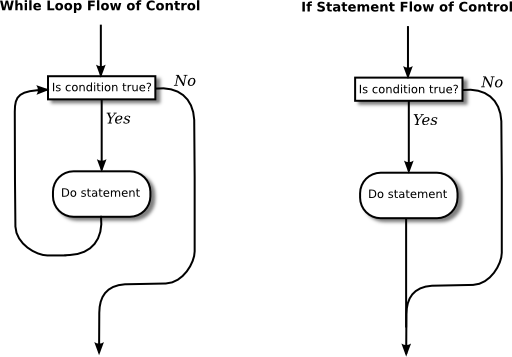

Sólo debemos tener en cuenta cuando programamos que el uso de un while es mucho más crítico que el uso de un for. **Esto es porque la condición lógica que controla el bucle debe aplicarse sobre una variable interna en el bucle. Entonces es probable que si programamos mal, la variable que usamos como control nunca llegue a cumplir la condición que nos para la ejecución**. En Matlab no suele ser un gran problema, puesto que el sistema puede reaccionar y cortar el proceso de otro modo, pero en otros lenguajes puede tener consecuencias bastante desagradables. También debemos tener en cuenta que los bucles controlados por una condición lógica no permiten la paralelización en el caso que tengamos una versión para varios procesadores de Matlab [Nogueras, Guillem, 2007].

## Sentencia bucle

Si lo que se busca hacer es un bucle la estructura más básica es el ***for****.* Estructura de control destinada a realizar un numero finito de ciclos una o varias acciones. Es decir, para una determinada variable, que avanza de 1 en 1 desde el límite inferior hasta el límite superior ejecutamos el cuerpo. El cuerpo puede depender o no de la variable contador, ésta puede ser un contador a parte, que simplemente nos imponga que una determinada sentencia se ejecute un número j de veces. La mayoría de las veces nuestro cuerpo dependerá de la variable que usemos como contador, es decir, será un índice de nuestro cuerpo.   

A continuacion algunos ejemplos en pseudocódigo y su respectiva sintaxis:


$$\textbf{Para } \text{i}\leftarrow x \textbf{ Hasta} \text{ n} \textbf{ Con Paso } \text{ z}\textbf{ Hacer}\\ \qquad  \text{instruciones;}
\\ \textbf{Fin Para}$$
 

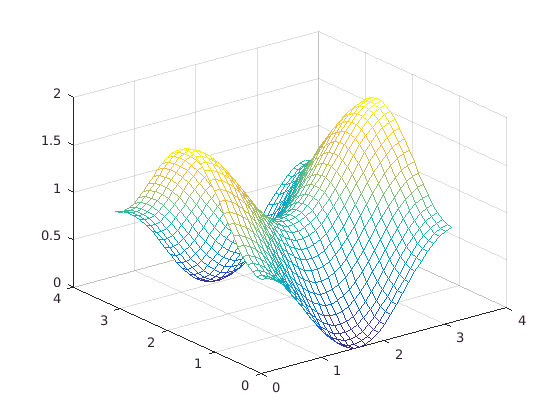

x = 0:0.1:pi; 
y = x';
for f = 1:length(x)
    for c = 1:length(y)
        z(f,c) = sin(x(f)).^2 + cos(y(c)).^2;
    end
end
figure
mesh(x,y,z);

# Funciones predefinidas 

Para aquellos que vengan de otros lenguajes les sorprenderá que no es necesario incluir, llamar o importar librerías, para disponer de funciones particulares. Resulta que en MATLAB, todas las funciones se encuentran disponibles por defecto, esto trae una gran deficiencia en términos de rendimientos a la hora de interpretar el código en tiempos de ejecución.

## Funciones sobre escalares

abs(-1) % Valor absoluto

ans = 1

cos(2*pi), sin(pi/2) % Funciones trigonometricas (argumento en radianes)

ans = 1

ans = 1

cosd(360), sind(90) % Funciones trigonometricas (argumento en grados)

ans = 1

ans = 1

exp(1i*pi) % Exponencial (identidad de Euler)

ans =   -1.0000 + 0.0000i


log10(1) % Logaritmo en base10

ans = 0

sqrt(4) % Raiz cuadrada

ans = 2

round (4.5) % Redondea al entero más proximo

ans = 5

floor(3.8) % Redondea al entero más proximo (hacia abajo)

ans = 3

ceil(4.1) % Redondea al entero más proximo (hacia aarriba)

ans = 5

## Funciones sobre vectores

max([1 23 4 56]) % Elemento máximo de un vector

ans = 56

min([-1 -50 501 12]) % Elemento mínimo de un vector

ans = -50

sort ([1 34 1 5]) % Ordena un vector en forma ascendente

ans =      1     1     5    34


sort ([1 34 1 5],'descend') % Ordena un vector en forma descendente

ans =     34     5     1     1


mean ([30 30 40]) % Promedio de los elementos de un vector

ans = 33.3333

fliplr([1 2 3 4]) % Dar vuelta los elementos del vector

ans =      4     3     2     1


repmat([1 2 3],2,1) % Copia el vector/matriz

ans =      1     2     3
     1     2     3


## Tamaño de los arreglos

length([1 2 3 4]) % Tamaño de la mayor dimensión

ans = 4

ndims([1 2 4]) % Número de dimensiones

ans = 2

numel([1 2 4]) % Número de elementos

ans = 3

[m, n] = size ([1 2 3; 4 5 6]) % Dimensiones de la matriz

m = 2

n = 3

## Pongamos en práctica lo aprendido antes que se nos olvide...

La **curva de olvido** ilustra la pérdida del conocimiento adquirido con el tiempo. Un **concepto relacionado con la intensidad del recuerdo**, que indica cuánto se mantiene un contenido en el cerebro. Cuanto más intenso sea un recuerdo, más tiempo se mantiene. Un gráfico  típico de la curva del olvido muestra que normalmente en unos días o semanas se olvida la mitad de lo que hemos aprendido, a no ser que lo repasemos. Una aproximación matemática a la curva de la memoria es la siguiente fórmula (Hermann Ebbinghaus):


$$R = e^{\frac{-t}{S}} \quad ,$$


donde **R** representa la curva de olvido, **S** la intensidad (porcentaje) de lo aprendido y **t **el tiempo en horas. Para acostumbranos a la metodología de trabajo, comencemos con plantear el pseudocódigo:


$$\text{S}\leftarrow s; \qquad // \quad Donde \quad 0\le s \le 100 \quad s \in  \Re  \\ 

T\leftarrow t_1, t_2, ...,t_n; \qquad // \quad t \in \mathcal{N}   \quad \land \quad 1\le n \le horas\\ 

R\leftarrow e^{(-T/s)};
$$


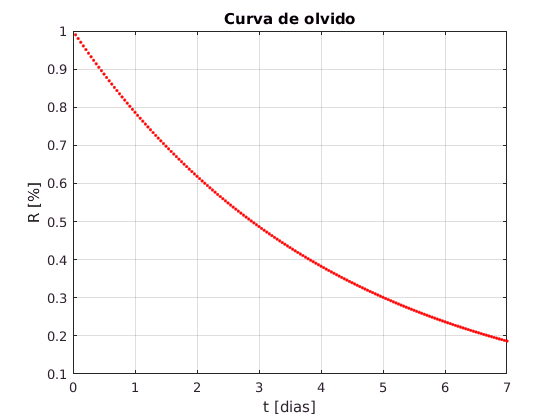

S = 100; 
T = 1:24*7;  % se amplia el dominio, para evaluarlo por dias.
R = exp(-T./S);

plot(T/24,R,'.r'); title('Curva de olvido'); ylabel('R [%]'); xlabel('t [dias]'); grid on;

% plot(T/24,R*100,'.r'); title('Curva de olvido'); ylabel('R [%]'); xlabel('t [dias]'); grid on;

Ahora el desafio es hacerlo para dos valores de **S**. Comencemos con plantear el pseudocódigo:


$$\text{S}\leftarrow
\left[ {\begin{array}{cc}
   S1 & S1 & \cdots & S1_{1,j} \\
   S2 & S2 &  \cdots  & S2_{2,j} \\
   \vdots & \vdots & \vdots & \vdots  \\
   Sp & Sp &  \cdots  & S2_{i,j} \\
  \end{array} } \right]; 
\qquad // \quad Donde \quad 0\le S_p \le 100 \quad S_p \in  \Re; \quad j\rightarrow horas  \\ 

T\leftarrow \left[ {\begin{array}{cc}
   T1 & T2 & \cdots & Tn_{1,j} \\
   T1 & T2 &  \cdots  & Tn_{2,j} \\
   \vdots & \vdots & \vdots & \vdots  \\
   T1 & T2 &  \cdots  & Tn_{i,j} \\
  \end{array} } \right]; 
\qquad  \qquad // \quad Tn \in \mathcal{N}   \quad \land \quad 1\le n \le j\\ 

R\leftarrow e^{(-T/s)};
$$


j = 168;
s = ones(2,j);
Sp = [100; 30];
S = [s(1,:)*Sp(1);s(2,:)*Sp(2)]

S =    100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100
    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30


t = s;
T = [t(1,:)*1:j; t(2,:)*1:j]

T =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


R = exp(-T./S)

R =     0.9900    0.9802    0.9704    0.9608    0.9512    0.9418    0.9324    0.9231    0.9139    0.9048    0.8958    0.8869    0.8781    0.8694    0.8607    0.8521    0.8437    0.8353    0.8270    0.8187    0.8106    0.8025    0.7945    0.7866    0.7788    0.7711    0.7634    0.7558    0.7483    0.7408    0.7334    0.7261    0.7189    0.7118    0.7047    0.6977    0.6907    0.6839    0.6771    0.6703    0.6637    0.6570    0.6505    0.6440    0.6376    0.6313    0.6250    0.6188    0.6126    0.6065
    0.9672    0.9355    0.9048    0.8752    0.8465    0.8187    0.7919    0.7659    0.7408    0.7165    0.6930    0.6703    0.6483    0.6271    0.6065    0.5866    0.5674    0.5488    0.5308    0.5134    0.4966    0.4803    0.4646    0.4493    0.4346    0.4204    0.4066    0.3932    0.3803    0.3679    0.3558    0.3442    0.3329    0.3220    0.3114    0.3012    0.2913    0.2818    0.2725    0.2636    0.2550    0.2466    0.2385    0.2307    0.2231    0.2158    0.2087    0.2019    0.1953    0

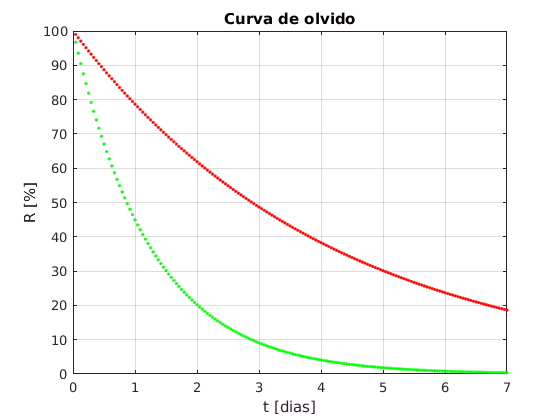

plot(T(1,:)/24,R(1,:)*100,'.r',T(2,:)/24,R(2,:)*100,'.g');title('Curva de olvido'); ylabel('R [%]'); xlabel('t [dias]'); grid on;

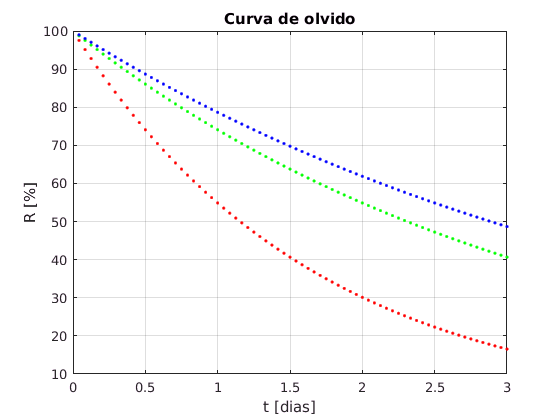


% Alternativa
j = 72;
S = repmat([40;80;100],1,j); 
T = repmat(1:j,3,1);
R = exp(-T./S);
p = plot(T(1,:)/24,R(1,:)*100,'.r',T(2,:)/24,R(2,:)*100,'.g', T(3,:)/24,R(3,:)*100,'.b');title('Curva de olvido'); ylabel('R [%]'); xlabel('t [dias]'); grid on;

Por ultimo, como puedo representar un ciclo de repasos, para obtener una curva como la siguiente:

R_ = [R(1,:) R(2,:) R(3,:)]

R_ =     0.9753    0.9512    0.9277    0.9048    0.8825    0.8607    0.8395    0.8187    0.7985    0.7788    0.7596    0.7408    0.7225    0.7047    0.6873    0.6703    0.6538    0.6376    0.6219    0.6065    0.5916    0.5769    0.5627    0.5488    0.5353    0.5220    0.5092    0.4966    0.4843    0.4724    0.4607    0.4493    0.4382    0.4274    0.4169    0.4066    0.3965    0.3867    0.3772    0.3679    0.3588    0.3499    0.3413    0.3329    0.3247    0.3166    0.3088    0.3012    0.2938    0.2865


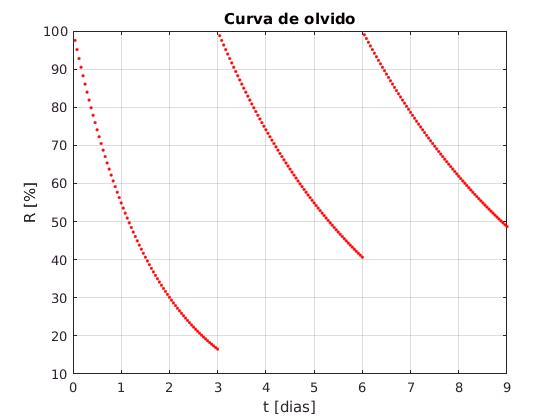

T_ = 1:24*3*3;
plot(T_/24,R_*100,'.r');title('Curva de olvido'); ylabel('R [%]'); xlabel('t [dias]'); grid on;

# Números complejos

Un **número complejo** z es un número que se puede representar como:


$$z = a +ib \quad,$$


donde $a, b \in \Re$y el signo $i$es la **unidad imaginaria** que satisface la ecuacion $i^2=-1$. Entonces podriamos decir que:


$$i = \sqrt{-1} \quad,
$$


a los numeros $a$ y $b$ los llamamos parte real y parte imaginaria de $z$ respectivamente:


$$\Re[z] = a \qquad \Im[z] = b \quad.$$


Cuatro formas de ingresar numeros complejos en MATLAB

3+1i*4 % binómica 

ans =    3.0000 + 4.0000i


complex(1,2) % par ordenado

ans =    1.0000 + 2.0000i


2*exp(1i*pi/6) % polar

ans =    1.7321 + 1.0000i


2*cos(pi/6) + 1i*2*sin(pi/6) % trigonométrica

ans =    1.7321 + 1.0000i


OBS: tambien podemos usar $j$ como unidad imaginaria. Entonces $j=i$ .

3+1j*4

ans =    3.0000 + 4.0000i


Las operaciones con números complejos se definen:


$$z_1 = x_1 +iy_1 = r_1 e^{(i\theta_1)} \quad ,$$



$$z_2 = x_2 + iy_2 = r_2 e^{(i\theta_2)} \quad,$$



$$z_1+z_2=(x_1+x_2)+i(y_1+y_2) \quad,$$


(2+1i*5)+(3-1i*2)

ans =    5.0000 + 3.0000i



$$z_1-z_2=(x_1-x_2)+i(y_1-y_2) \quad,$$


(2+1i*5)-(3-1i*2)

ans =   -1.0000 + 7.0000i



$$z_1*z_2=r_1r_2e^{i(\theta_1+\theta_2)} \quad,$$


(2+1i*5)*(3-1i*2)

ans =   16.0000 +11.0000i


(2+1i*5)/(3-1i*2)

ans =   -0.3077 + 1.4615i



$$z_1*z_2=(x_1x_2-y_1y_2)+i(x_1y_2+x_2y_1) \quad ,$$



$$\frac{z_1}{z_2} = \frac{r_1}{r_2}e^{i(\theta_1-\theta_2)} \quad ,$$


z1 = 2*exp(1i*pi/6)

z1 =    1.7321 + 1.0000i


z2 = 1*exp(1i*pi/3) % producto de dos números complejos en forma polar

z2 =    0.5000 + 0.8660i


z = z1*z2

z =    0.0000 + 2.0000i


abs(z) % magnitud

ans = 2

angle(z) % angulo en radianes

ans = 1.5708


$$\pi rad = 180/\pi grad \quad,$$


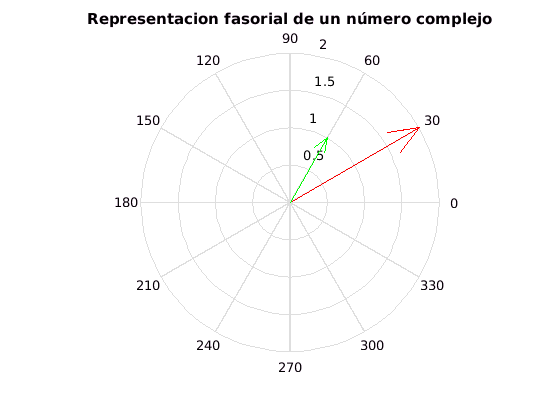

compass(z1,'-r'); title('Representacion fasorial de un número complejo'); hold on; compass(z2,'-g'); hold off;

## Ejercicios de la guía n°0 (script_01_01, ejemplo)

Los siguientes ejercicios de la guia n°1, pueden ser resueltos con MATLAB:

1) Efecuar las siguientes operaciones:


$$a) i(1-\sqrt{3})(\sqrt{3}+i)$$
                
$$b) \frac{5i}{1+i}$$
               
$$c)(1-i\sqrt{2})^3$$


3) Hallar los módulos y los ángulos que forman con el eje x los números $(2+j\sqrt{3})$y$(2-j\sqrt{3})^2$

4) Calcular la expresión $\frac{(1+j)}{\sqrt{3}+j}$ empleando la forma cartesiana y polar, respectivamente.

6) Calcular la magnitud y la fase de $(e^j+e^{3j})$

% script1
% open ('script_01_01')

Si no estas posicionado sobre la carpeta que contiene el script, MATLAB responde con un error, dado que no encuentra el archivo, en este caso: "script_01_01.m". Para resolver esto, es necesario modificar la Current Folder (Carpeta actual).

## ¿Cómo hacer un helloWord.m? (script_01_02)

Nuestro primer script va a calcular la velocidad del sonido $c$ [m/s] en el aire a partir de la ecuación de Boyle­Mariotte [Möser M., Barros J.L, 2009]:


$$c(t) =\sqrt{k\frac{R}{M_{mol}}{t} \quad,$$
 

esta depende solo del medio y de la temperatura absoluta, pero no de la presión o densidad estáticas. Si se ingresan los **valores típicos para el aire**:  

- $M_{mol}$ = 28,8 x 10^-3  kg/mol

- $t$ = 288 K (15ºC)

- $k$=1,4

- $R$ = 8,314 J/mol K como J= N m, N=kg m/s 2  

Abrir un nuevo script y realizarlo para un intervalo de temperaturas.

% edit
% script2
% open ('script_01_02.m')

Al guardar el script no utilizar **mayusculas **o **números** para iniciar el nombre del archivo.

# Referencias

- **Datos y variables**. 2009.

- Mat.caminos.upm.es. ***Lenguaje de programación - MateWiki***. Available at:  [https://mat.caminos.upm.es/wiki/Lenguaje_de_programaci%C3%B3n#Tipado_est.C3.A1tico_y_din.C3.A1mico](https://mat.caminos.upm.es/wiki/Lenguaje_de_programaci%C3%B3n#Tipado_est.C3.A1tico_y_din.C3.A1mico). Universidad Politécnica de Madrid. 2017.

- Nogueras, Guillem. ***Introducción informal a Matlab y Octave.*** Universidad Politecnica de Madrid, 2007.

- Möser, Michael; Barros, José Luis. ***Ingeniería acústica: Teoría y aplicaciones***. Springer Science & Business Media, 2009.